# Describe Images Using ChatGPT™

This example shows how to generate image descriptions using the addUserMessageWithImages function. To run this example, you need a valid API key from a paid OpenAI™ API account.

loadenv(".env")
addpath('..') 

## Load and Display Image Data

Load the sample image from Wikipedia. Use the `imread` function to read images from URLs or filenames.

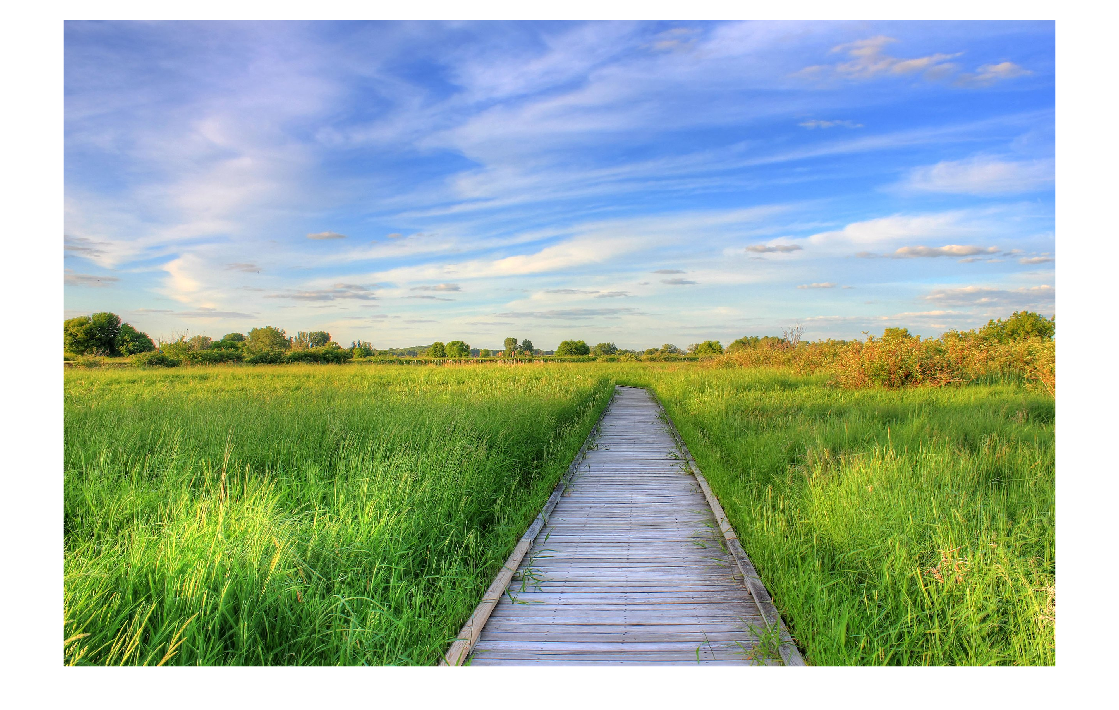

image_url = 'https://upload.wikimedia.org/wikipedia/commons/thumb/d/dd/Gfp-wisconsin-madison-the-nature-boardwalk.jpg/2560px-Gfp-wisconsin-madison-the-nature-boardwalk.jpg';
im = imread(image_url);
imshow(im)

## Generate Image Descriptions

Ask questions about the image with the URL. Select `gpt-4-vision-preview` model to create a chat object

chat = openAIChat("You are an AI assistant.", ModelName="gpt-4-turbo"); 

Create a message and pass the image url along with the prompt.

messages = openAIMessages;
messages = addUserMessageWithImages(messages,"What is in the image?", string(image_url));

Generate a response. By default, the model returns a very short reponse. To override it, set `MaxNumTokens` to 4096 or lower. 

[txt,~,response] = generate(chat,messages,MaxNumTokens=4096);
if response.StatusCode == "OK"
    wrappedText = wrapText(txt)
else
    response.Body.Data.error
end

wrappedText =     "The image shows a wooden boardwalk path extending through a vibrant green grassy field.
     The scene is in a natural setting with a clear sky above showcasing some scattered clouds.
     In the distance, a line of trees or shrubbery is visible, dividing the grassland from the sky.
     The overall appearance suggests a tranquil, natural environment that may be part of a park, nature reserve, or wetland area.
     The time of day appears to be either late afternoon or early evening judging from the soft, warm light and the shadows, indicative of a setting sun."


## Helper function

function wrappedText = wrapText(text)
    wrappedText = splitSentences(text);
    wrappedText = join(wrappedText,newline);
end

*Copyright 2024 The MathWorks, Inc.*